# MHKiT Short-term Extreme Loads

Short-term extreme loads are typically required as part of a long-term extreme load estimate. A short-term extreme distribution is a probability distribution for the extreme value of a short-term (e.g. 3-hours) time-series.

MHKiT includes functions adapted from the WDRT for estimating the short-term extreme distribution. Several methods are included, which can be divided into two main approaches:

- Block maxima: approximate the short-term extreme distribution directly by fitting a probability distribution to the maxima from N distinct short-term blocks.

- Peaks distribution: approximate the short-term extreme distribution from the distribution of peaks from a time-series of arbitrary length.

The two sets of methods will be demonstrated.

**NOTE**: This notebook will walk through the two different approaches, and each method in them. The short-term extremes will be obtained step-by-step showing the intermediate outputs. However, a convenience function, the `loads.extreme.short_term_extreme `function, can be be used directly in a single step. For this usage jump to the last section. It is recommended that you go over this entire example to understand what is going on "under the hood" prior to using this convenience function.

The quantity (load) of interest can be anything related to the WEC, such as position (e.g. PTO extension, heave displacement), velocity, structural load, mooring loads, etc. For this example we will use the wave elevation as the quantity of interest, since such time-series can be easily created without having to run a WEC-modeling software. The short-term period of interest will be 3-hours.

An important pre-processing step is making the time-series zero-mean. In this case, since wave elevation is zero-mean no pre-processing is needed.

We first define the short-term period (3 hours).

% short-term period in seconds
t_st = 3.0 * 60.0 * 60.0 

t_st = 10800

The methods based on peaks distributions require a single time series of any length while the methods based on block maxima require N time series of length equal to the short-term time period.

We will now create N=10 time series of length equal to the short-term period (3 hours). For block maxima methods we will use all 10 and for peaks distribution methods we will only use the first hour of the first time-series. For the block maxima we use N=10 for speed considerations, but note that this would be inadequately small for most real applications.

For the sake of example we will consider the wave elevation as the quantity of interest (can be thought as a proxy for heave motion in this example). Wave elevation time-series for a specific sea state can be created quickly without running any external software.

**NOTE:** The code below is simply creating the synthetic data (wave elevation time series). In a realistic case the time series would be obtained externally, e.g. through simulation software such as WEC-Sim or CFD. For this reason the details of creating the synthetic data are not presented here, instead assume for the quantity of interest there are ten 3-hours time-series available.

We start by creating the ten 3-hour time-series of the quantity of interest. We do this with a list comprehension and using the `wave.resource.surface_elevation` function. The result is a list of 10 different time-series. Alternatively we could have created a single time-series of length N times the short-term period (30 hours) and used the `extreme.block_maxima` function to split it into blocks and return the block maxima.

% JONSWAP spectrum for creating short-term time-series
T_min = 1;  % s
Tp = 8;  % s
Hs = 1.5;  % m
df = 1/t_st;
f_max = 1/T_min;
Nf = f_max/df + 1;
f = linspace(0.0, f_max, Nf);
S = jonswap_spectrum(f, Tp, Hs);

% time in seconds
time = linspace(0, t_st, 2*Nf+1);

% qoi timeseries
qoi_timeseries = surface_elevation(S, time);
qoi = qoi_timeseries.elevation;

We can view the different time-series. Change value of `i `below to plot a different time-series. Below we plot both the full 3 hours time series and the first 2 minutes to get a better look at the behavior of the response.

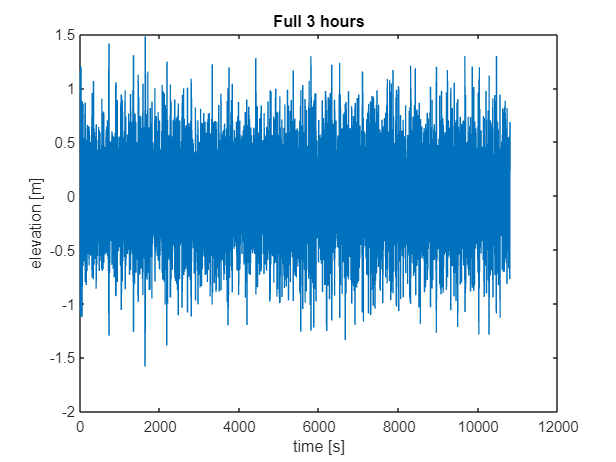

figure; 
plot(time, qoi)
title("Full 3 hours"); xlabel("time [s]"); ylabel("elevation [m]")

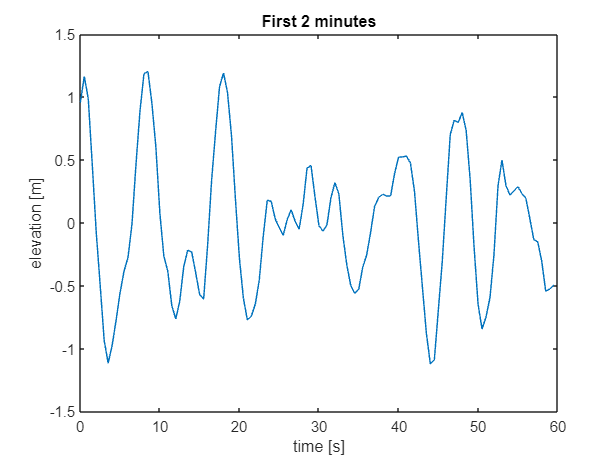

figure; 
plot(time(1:120), qoi(1:120))
title("First 2 minutes"); xlabel("time [s]"); ylabel("elevation [m]")

### Block Maxima

The short-term extreme distribution can be estimated directly from N time-series of short-term period. These time-series can be obtained, for instance, from N distinct simulations of the quantity of interest, or alternatively by dividing a long time-series of the quantity of interest into blocks of length equal to the short-term period. In this example we will divide our 3 hour time series into 10-minute segments for speed considerations, but this would be inadequately small for most real applications.

#### 1. Find the maximum of each block

The first step is to get the maximum in each block, i.e. in each of the 10-minute time series. We can use the `block_maxima` funtion to do this for us.

% split time series into 10-minute (600s) segments
block_max = block_maxima(time, qoi', 600);

We can also visualize this result, which represents the maximum elevation of each 10-minute segment for the 3 hour period we are analyzing.

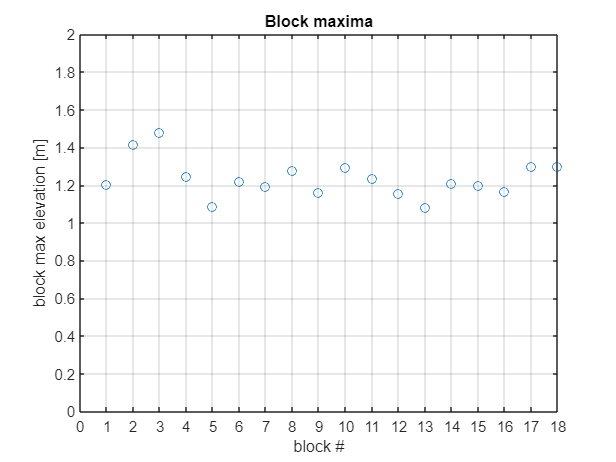

figure;
plot(block_max, 'o'); grid on; xticks(0:1:19); ylim([0,2])
xlabel('block #'); ylabel('block max elevation [m]'); title('Block maxima')

#### 2. Fit a distribution to the block maxima

We can now get the short-term extreme distribution by fitting either a generalized extreme value distribution or a Gumbel (right) distributions to these N=18 maxima. We will compare both methods.

% generalized extreme value distribution
x = linspace(0,3,1000);
ste_gev_pdf = ste_block_maxima_gev(block_max, x, "pdf");
ste_gev_cdf = ste_block_maxima_gev(block_max, x, "cdf");
ste_gum_pdf = ste_block_maxima_gumbel(block_max, x, "pdf");
ste_gum_cdf = ste_block_maxima_gumbel(block_max, x, "cdf");

The outputs of these functions are probability distributions. Here we will plot the CDF and PDF and print the 95% interval for both methods.

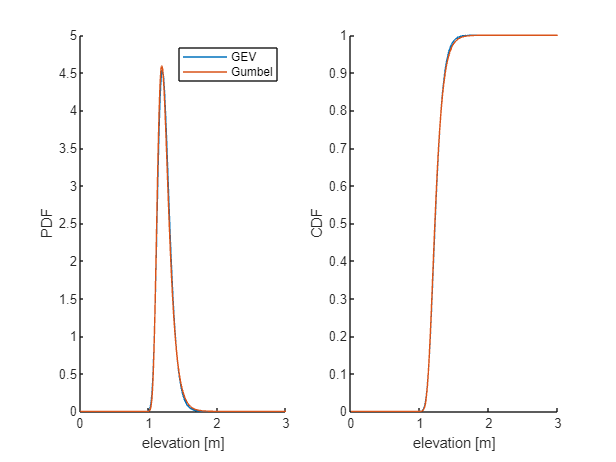

% plot cdf and pdf
subplot(1,2,1); hold on; 
plot(x,ste_gev_pdf); xlabel('elevation [m]'); ylabel('PDF')
plot(x,ste_gum_pdf); xlabel('elevation [m]'); ylabel('PDF')
legend('GEV','Gumbel')
subplot(1,2,2); hold on; 
plot(x,ste_gev_cdf); xlabel('elevation [m]'); ylabel('CDF')
plot(x,ste_gum_cdf); xlabel('elevation [m]'); ylabel('CDF')

fprintf('GEV:\n 95 percent interval: (%.3f m, %.3f m)',ste_block_maxima_gev(block_max, 0.025, "ppf"),ste_block_maxima_gev(block_max, 0.975, "ppf"))

GEV:
 95 percent interval: (1.081 m, 1.459 m)

fprintf('GUMBEL:\n 95 percent interval: (%.3f m, %.3f m)',ste_block_maxima_gumbel(block_max, 0.025, "ppf"),ste_block_maxima_gumbel(block_max, 0.975, "ppf"))

GUMBEL:
 95 percent interval: (1.084 m, 1.483 m)

### Peaks Distribution

The block maxima approach is the most direct way to approximate the short-term extreme but it requires a lot of data (N timeseries of length equal to the short-term period). An alternative approach approximates the short-term extreme from a timeseries of arbitrary length, even shorter than the short-term period, by fitting a distribution to the peaks of the timeseries.

To demonstrate these methods we will approximate the 3-hour short-term extreme distribution from a single 1-hour timeseries.

We start by generating this 1-hour response timeseries.

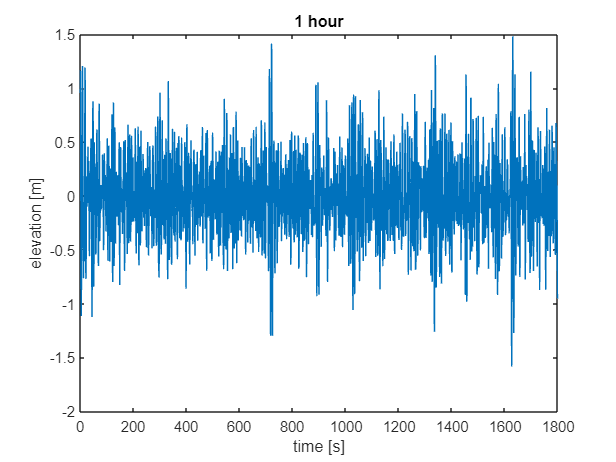

t_end = 1.0 * 60.0 * 60.0;
qoi_1hr = qoi(1:t_end);
time_1hr = time(1:t_end);
% visualize
figure; 
plot(time_1hr, qoi_1hr)
title("1 hour"); xlabel("time [s]"); ylabel("elevation [m]")

#### 1. Find the global peaks

The global peaks are the maximum between succesive zero-upcrossings. We use the `extreme.global_peaks` function to find these peaks.

[t_peaks, qoi_peaks] = global_peaks(time_1hr, qoi_1hr);
npeaks = length(qoi_peaks)

npeaks = 305

We will plot the entire time-series and the global peaks and then zoom in on the first 2 minutes.

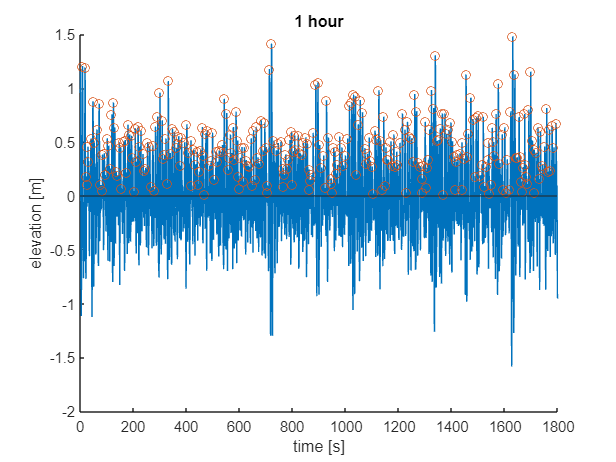

figure; hold on;
plot(time_1hr, qoi_1hr)
title("1 hour"); xlabel("time [s]"); ylabel("elevation [m]")
scatter(t_peaks, qoi_peaks)
yline(0)

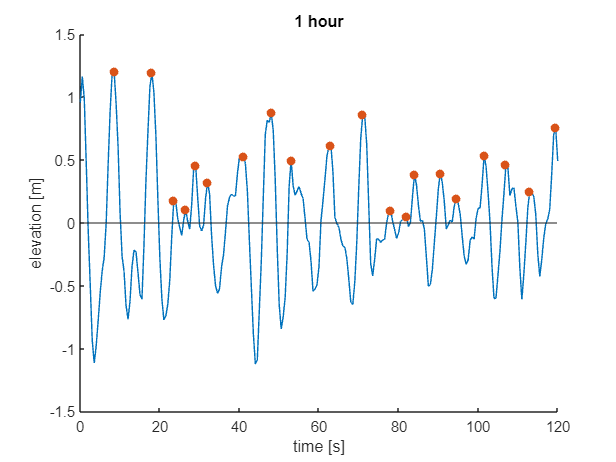

figure; hold on;
plot(time_1hr, qoi_1hr)
title("1 hour"); xlabel("time [s]"); ylabel("elevation [m]")
scatter(t_peaks, qoi_peaks, 'filled')
yline(0)
xlim([0,120])

#### 2. Fit a distribution to the peaks

MHKiT has three methods for doing this.

- Fit a Weibull distribution to all the peaks.

- Weibull tail fit: seven different weibull distributions are fit to successively smaller subsets of the highest peaks, and the peak distribution is taken as the average of these sevenn

- Peaks over threshold: a generalized Pareto distribution is fit to all peaks above a certain threshold, typically taken as 1.4 standard deviations above the mean.

We will now compare the results from these three methods. For the peaks over threshold we will take the threshold (variable thresh below) to be 1.4 standard deviations above the mean. Note in this example, we are also storing the python statistical object. This is something we will need in the step!

% Weibull
[peaks_w_pdf, peaks_w] = peaks_distribution_weibull(qoi_peaks, x, "pdf");
peaks_w_cdf = peaks_distribution_weibull(qoi_peaks, x, "cdf");
% Weibull tail fit
[peaks_wtf_pdf, peaks_wtf] = peaks_distribution_weibull_tail_fit(qoi_peaks, x, "pdf");
peaks_wtf_cdf = peaks_distribution_weibull_tail_fit(qoi_peaks, x, "cdf");
% peaks over threshold
thresh = mean(qoi_peaks) + 1.4 * std(qoi_peaks);
[peaks_pot_pdf, peaks_pot] = peaks_distribution_peaks_over_threshold(qoi_peaks, x, "pdf", "threshold", thresh);
peaks_pot_cdf = peaks_distribution_peaks_over_threshold(qoi_peaks, x, "cdf", "threshold", thresh);

We will plot both the PDF and CDF of the peaks distribution, and obtain the 95% interval for each distribution. Note however that for the peaks over threshold method the distribution is only defined for values over the threshold, and many of the functionalities that require the entire distribution are therefore not available.

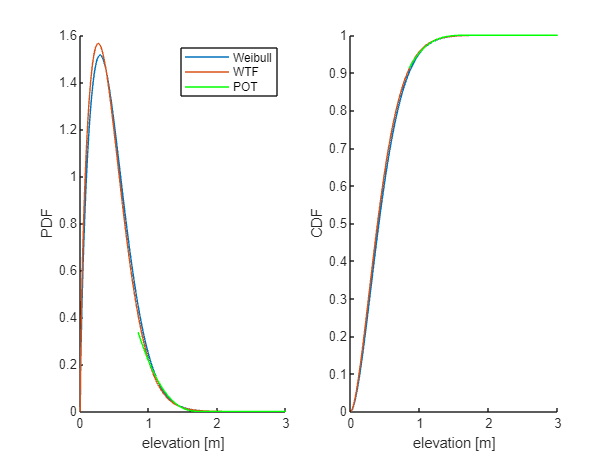

% plot cdf and pdf
subplot(1,2,1); hold on; 
plot(x,peaks_w_pdf); xlabel('elevation [m]'); ylabel('PDF')
plot(x,peaks_wtf_pdf); xlabel('elevation [m]'); ylabel('PDF')
plot(x,peaks_pot_pdf,'green'); xlabel('elevation [m]'); ylabel('PDF')
legend('Weibull','WTF','POT')
subplot(1,2,2); hold on; 
plot(x,peaks_w_cdf); xlabel('elevation [m]'); ylabel('CDF')
plot(x,peaks_wtf_cdf); xlabel('elevation [m]'); ylabel('CDF')
plot(x,peaks_pot_cdf, 'green'); xlabel('elevation [m]'); ylabel('CDF')

s1 = sprintf('Weibull:\n 95 percent interval: (%.3f m, %.3f m)\n',peaks_distribution_weibull(qoi_peaks,0.025,"ppf"),peaks_distribution_weibull(qoi_peaks,0.975,"ppf"));
s2 = sprintf('Weibull tail fit:\n 95 percent interval: (%.3f m, %.3f m)',peaks_distribution_weibull_tail_fit(qoi_peaks,0.025,"ppf"),peaks_distribution_weibull_tail_fit(qoi_peaks,0.975,"ppf"));
disp([s1, s2])

Weibull:
 95 percent interval: (0.055 m, 1.122 m)
Weibull tail fit:
 95 percent interval: (0.049 m, 1.101 m)


#### 3. Obtain the short-term extreme distribution from the peaks distribution

We do this using the peaks distribution and an approximation for the number of peaks per short-term period. We use the `extreme.ste_peaks` function to obtain an approximation for the number of peaks in a short-term period.

N_st = number_of_short_term_peaks(npeaks, t_end, t_st);
fprintf("Approximate number of peaks in a (3-hours) short-term period: %d",N_st)

Approximate number of peaks in a (3-hours) short-term period: 915

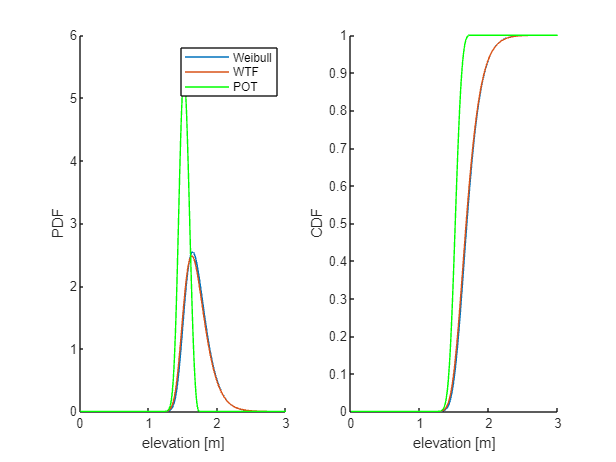

% 
ste_w_pdf = ste_peaks(peaks_w, N_st, x, "pdf");
ste_w_cdf = ste_peaks(peaks_w, N_st, x, "cdf");
ste_wtf_pdf = ste_peaks(peaks_wtf, N_st, x, "pdf");
ste_wtf_cdf = ste_peaks(peaks_wtf, N_st, x, "cdf");
ste_pot_pdf = ste_peaks(peaks_pot, N_st, x, "pdf");
ste_pot_cdf = ste_peaks(peaks_pot, N_st, x, "cdf");

% plot cdf and pdf
figure;
subplot(1,2,1); hold on; 
plot(x,ste_w_pdf); xlabel('elevation [m]'); ylabel('PDF')
plot(x,ste_wtf_pdf); xlabel('elevation [m]'); ylabel('PDF')
plot(x,ste_pot_pdf, 'green'); xlabel('elevation [m]'); ylabel('PDF')
legend('Weibull','WTF','POT')
subplot(1,2,2); hold on; 
plot(x,ste_w_cdf); xlabel('elevation [m]'); ylabel('CDF')
plot(x,ste_wtf_cdf); xlabel('elevation [m]'); ylabel('CDF')
plot(x,ste_pot_cdf, 'green'); xlabel('elevation [m]'); ylabel('CDF')

### The `short_term_extreme` function

This example showed step-by-step how to estimate the short-term extreme using different methods. However for most use cases the results from the intermediate steps are not of interest. The estimated short-term extreme distribution can be obtained directly from a time-series of the response using the `short_term_extreme function`. For the methods based on fitting the peaks the time-series can be of arbitrary length, while for methods based on block maxima it should be many times longer than the short-term period.

**Note**: This function is provided for convenience but the user should be aware of what is going on "under the hood" and ensure the method they choose is appropriate. For instance if using a block maxima method it is good practice to have at least 20 short-term periods worth of data.

As an example the Weibull tail fit approximation of the short-term extreme distribution can be obtained in a single step. The function takes the time series (time, response), the desired short-term period, and the method as inputs.

ste_wtf = short_term_extreme(time_1hr, qoi_1hr, t_st, "peaks_weibull_tail_fit", x, "pdf");